file = "data\perf_gcs_rand_corridor2.csv";
data = importdata(file, ',', 1);
tottime = data.data(:, 4);
bordersize = data.data(:, 5);



h = figure('Position',[0,0,1200,600]);

% Curve fit
% subplot('Position',[0.5 0 0.5 0.9]);
subplot(1,4,[2,3,4])
hold on;
axis([0, 150, 0 ,4]);
xticks(0:20:160);
yticks(0:1:4);
grid('minor');
plot(bordersize, tottime,".",  "Color", [0.5,0.5,0.5]);
[fitresult, gof] = fit_bordersize_searchtime2(bordersize, tottime, true)

fitresult =      常规模型:
     fitresult(x) = a*exp(b*x)
     系数(置信边界为 95%):
       a =     0.07935  (0.0698, 0.0889)
       b =     0.02612  (0.02495, 0.02728)

gof = 包含以下字段的 struct :
           sse: 126.7994
       rsquare: 0.5650
           dfe: 998
    adjrsquare: 0.5646
          rmse: 0.3564


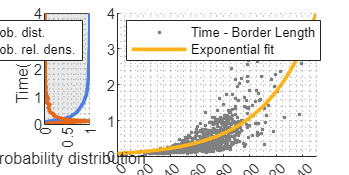

hold off;
% probability distribution

Y = tottime;
time_range = [0, 4];
resolution = 100;
time_res = linspace(time_range(1), time_range(2), resolution+1);
cnt = zeros(1, resolution+1);
cnt_accum = zeros(1, resolution+1);
for i = 1:length(Y)
    for j = 1:resolution
        if Y(i) >= time_res(j) && Y(i) < time_res(j+1)
            cnt(j) = cnt(j) + 1;
            break;
        end
    end
end
for i = 1:resolution
    cnt_accum(i+1) = cnt_accum(i) + cnt(i);
end

subplot(1,4,1)
hold on;
axis([0, 1, 0 ,4]);
yticks(0:1:4);
xticks(0:0.5:1);
grid('minor');
ylabel( 'Time(ms)', 'Interpreter', 'none' );
xlabel( 'Probability distribution', 'Interpreter', 'none' );

area(cnt_accum/length(tottime),time_res, "LineWidth", 2, ...
    "FaceColor", [0.7, 0.7, 0.7], "FaceAlpha", 0.3, ...
    "EdgeColor", [0.3, 0.5, 0.9]);
area(cnt_accum/length(tottime),time_range(2), "LineWidth", 1, ...
    "FaceColor", [1, 0.7, 0.1], "FaceAlpha", 0.3, ...
    "EdgeColor", [1, 0.7, 0.1]);
plot(cnt/max(cnt),time_res, "LineWidth", 2, "Color", [0.9, 0.4, 0.1]);
 legend(  'Prob. dist.', '', 'Prob. rel. dens.', 'Location', 'North')
hold off;